% Last edited
Last_edited = datestr(now,1)

Last_edited = '28-May-2023'

clear Last_edited

## Load the data and write them to a table

clear; close all; clc;
addpath __self_func__/

addpath Data_Formal/

addpath pre_limits/


if ~ exist('data_clear/')
    mkdir data_clear/
    mkdir data_clear/plots/
end

subids = [1:5,10:12,15:17];
subnames = {'lx','SLJ','李卓然','cmj','hyf','cyl','sjj','hhl','xkd','wyb','SJQ'};

pre_JNDs = zeros(length(subnames),1)

pre_JNDs =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% for id = 1:length(subids)
%     if subids(id) ~= 13
%         load(['pre_limit_',num2str(subids(id)),subnames{id},'.mat']);
%         pre_JNDs(id) = JND;
%     end
% end
figure
exact_JND = [0.7916
    0.7178
    0.8039
    0.7024
    0.9734
    1.77848170481830
    0.762189147547140
    1.25517576383264
    1.23751468030922
    1.02438284234854
    0.797269084191502
    1.20179003122792
    0.998282567406804]

exact_JND =     0.7916
    0.7178
    0.8039
    0.7024
    0.9734
    1.7785
    0.7622
    1.2552
    1.2375
    1.0244


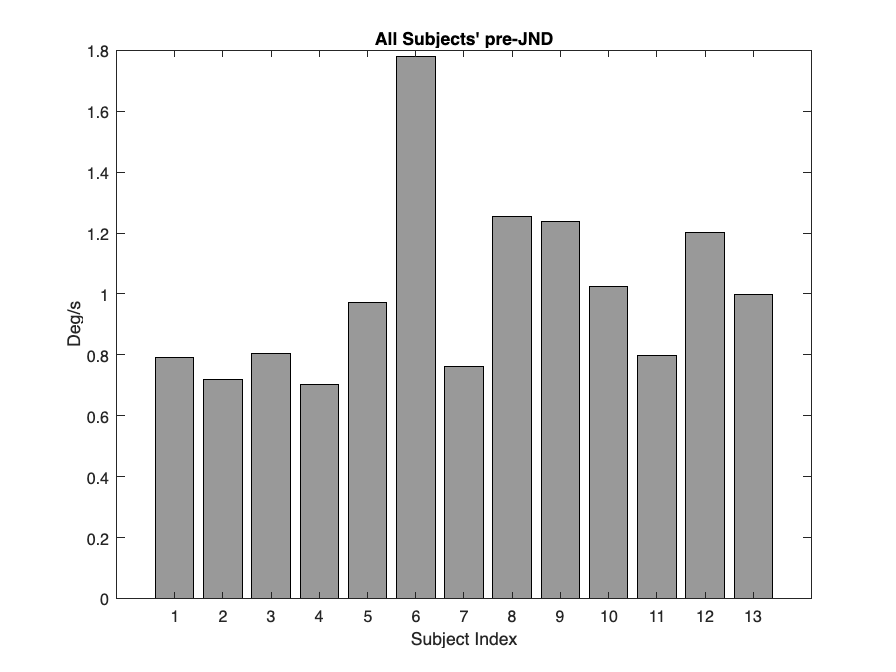

bar(exact_JND ,'FaceColor',"#999999")
xlabel('Subject Index')
ylabel('Deg/s')
title("All Subjects' pre-JND")

## Convert to Clearer Data

for id = 1:length(subids)
    load(['Results_',num2str(subids(id)),'_',subnames{id},'.mat']);

    % col_con = all_conds(:,3);
    % inf_con = all_conds(:,4);
    % aud_con = all_conds(:,5);
    velocity = zeros(length(trajectories),2);
    for ti = [1:length(trajectories)]
        currenttrial = trajectories{ti,1};
        velocity(ti,:) = currenttrial.velocity;
    end
    Vs = round(velocity,2);
    V_con = Vs(:,1); V_exp = Vs(:,2);
    res = res'; correct_ans = correct_ans'; yesno = yesno'; RTs = RTs';

    result_name = ['Results_',num2str(id),'.mat'];
    save(result_name,"V_exp","V_con","all_conds","res","correct_ans","yesno","RTs")
end

clear; close all; clc;
addpath __self_func__/


## Draw PsychMetricCurves

subids = [1:8];


% save all the params
PSEs = zeros(length(subids),7); % audio / color / interference
JNDs = zeros(length(subids),7);
d_primes = zeros(length(subids),7);
criterions = zeros(length(subids),7);

figure
Conditions = {'Aud','Col','Inf'};
legends = {["Averaged Data","No Audio","Audio"],["Averaged Data","Red","Green"]...
    ["Averaged Data","No Inf","Inf"]};
Colors = [{"#BEB8DC"},{"#FFBE7A"};{"#FA7F6F"},{"#8ECFC9"};{"#E7DAD2"},{"#999999"}];
for id = subids

    load(['Results_',num2str(id),'.mat']);
    col_con = all_conds(:,3);
    inf_con = all_conds(:,4);
    aud_con = all_conds(:,5);
    clear all_conds

    % convert data from pix/frame to deg/s
    V_exp = round(V_exp / (mean(V_con) / 4.5),2);
    Summary_table = table(V_exp,aud_con,col_con,inf_con,res,correct_ans,yesno,RTs);
    % % Clean data; rid of extreme RTs and no resp
    % idx  = find(abs(Summary_table.RTs - mean(Summary_table.RTs))...
    %     < 3*std(Summary_table.RTs) & Summary_table.RTs ~= -1);
    % Summary_table = Summary_table(idx,:);
    Summary_table = renamevars(Summary_table,["res","correct_ans","yesno","RTs"],...
        ["res","exphigher","accuracy","RT"]);

    % audiovisual integration
    mean_acc = groupsummary(Summary_table,"V_exp",'mean').mean_accuracy;
    all_exp_levels = groupsummary(Summary_table,"V_exp").V_exp;
    Summary_No_aud = Summary_table(Summary_table.aud_con == 1,:);
    acc_No_aud = groupsummary(Summary_No_aud,"V_exp",'mean').mean_accuracy;
    Summary_aud = Summary_table(Summary_table.aud_con == 2,:);
    acc_aud = groupsummary(Summary_aud,"V_exp",'mean').mean_accuracy;
    accs = [acc_No_aud, acc_aud];
    Average_choose_exp = [1-mean_acc(1:4);mean_acc(5:end)];
    Aud_choose_exp = zeros(length(all_exp_levels),2);
    Aud_choose_exp([1:4],:) = 1 - accs([1:4],:);
    Aud_choose_exp(5:end,:) = accs(5:end,:);
    % color difference
    Summary_red = Summary_table(Summary_table.col_con == 1,:);
    acc_red = groupsummary(Summary_red,"V_exp",'mean').mean_accuracy;
    Summary_green = Summary_table(Summary_table.col_con == 2,:);
    acc_green = groupsummary(Summary_green,"V_exp",'mean').mean_accuracy;
    accs = [acc_red, acc_green];
    Col_choose_exp = zeros(length(all_exp_levels),2);
    Col_choose_exp([1:4],:) = 1 - accs([1:4],:);
    Col_choose_exp(5:end,:) = accs(5:end,:);
    % inteference
    Summary_No_inf = Summary_table(Summary_table.inf_con == 1,:);
    acc_No_inf = groupsummary(Summary_No_inf,"V_exp",'mean').mean_accuracy;
    Summary_inf = Summary_table(Summary_table.inf_con == 2,:);
    acc_inf = groupsummary(Summary_inf,"V_exp",'mean').mean_accuracy;
    accs = [acc_No_inf, acc_inf];
    Inf_choose_exp = zeros(length(all_exp_levels),2);
    Inf_choose_exp([1:4],:) = 1 - accs([1:4],:);
    Inf_choose_exp(5:end,:) = accs(5:end,:);
    current_table = table(all_exp_levels,Average_choose_exp,...
        Aud_choose_exp,Col_choose_exp,Inf_choose_exp);

    eval(sprintf('Subj_%d_speed_choose = current_table',id))

    %%%%%%%% Calculate the dprime and criterion
    [dprime_all,c_all] = dprime(mean(Average_choose_exp([5:8],1)),mean(Average_choose_exp([1:4],1)));
    [dprime_No_aud,c_No_aud] = dprime(mean(Aud_choose_exp([5:8],1)),mean(Aud_choose_exp([1:4],1)));
    [dprime_aud,c_aud] = dprime(mean(Aud_choose_exp([5:8],2)),mean(Aud_choose_exp([1:4],2)));
    [dprime_red,c_red] = dprime(mean(Col_choose_exp([5:8],1)),mean(Col_choose_exp([1:4],1)));
    [dprime_green,c_green] = dprime(mean(Col_choose_exp([5:8],2)),mean(Col_choose_exp([1:4],2)));
    [dprime_No_inf,c_No_inf] = dprime(mean(Inf_choose_exp([5:8],1)),mean(Inf_choose_exp([1:4],1)));
    [dprime_inf,c_inf] = dprime(mean(Inf_choose_exp([5:8],2)),mean(Inf_choose_exp([1:4],2)));
    d_primes(id,:) = [dprime_all;dprime_No_aud;dprime_aud;dprime_red;dprime_green;...
        dprime_No_inf;dprime_inf];
    criterions(id,:) = [c_all;c_No_aud;c_aud;c_red;c_green;...
        c_No_inf;c_inf];


    %%%%%%%% Fit the curves and draw
    %%%%%%%% save the individual params
    % Plot the made up data
    fillin = 2;
    targets = [0.25, 0.5, 0.75]; % 25%, 50% and 75% performance
    weights = ones(1,length(all_exp_levels)); % No weighting
    [coeffs_all, stats_all, curve_all, threshold_all] = ...
        FitPsychCurveLogit(all_exp_levels, Average_choose_exp(:,1), weights, targets);
    PSEs(id,1) = [threshold_all(2)]; % audio / color / interference
    JNDs(id,1) = [(threshold_all(3) - threshold_all(1))/2];
    for pi = 1:3
        subplot(length(subids),3,3*(id-1)+pi)
        eval(sprintf('choose_exp = %s_choose_exp;',Conditions{pi}));
        s1 = scatter(all_exp_levels,Average_choose_exp,100,"MarkerEdgeColor","#999999",...
            "MarkerFaceColor","#82B0D2");
        hold on
        s2 = scatter(all_exp_levels,choose_exp(:,1),100,"MarkerEdgeColor","#999999",...
            "MarkerFaceColor",Colors{pi,1});
        hold on
        s3 = scatter(all_exp_levels,choose_exp(:,2),100,"MarkerEdgeColor","#999999",...
            "MarkerFaceColor",Colors{pi,2});
        if pi ==1
            ylabel('Choose Faster')
        end
        if id == subids(end)
            xlabel('Speed (deg/s)')
        end
        ylim([0,1])
        % Fit to the Psychometric curve
        % Fit for all conditions
        [coeffs_con1, stats_con1, curve_con1, threshold_con1] = ...
            FitPsychCurveLogit(all_exp_levels, choose_exp(:,1), weights, targets);
        [coeffs_con2, stats_con2, curve_con2, threshold_con2]  = ...
            FitPsychCurveLogit(all_exp_levels, choose_exp(:,2), weights, targets);
        plot(curve_all(:,1), curve_all(:,2), 'LineStyle', '--','Color',"#82B0D2",...
            "LineWidth",3);
        hold on
        plot(curve_con1(:,1), curve_con1(:,2), 'LineStyle', '--','Color',Colors{pi,1},...
            "LineWidth",3);
        hold on
        plot(curve_con2(:,1), curve_con2(:,2), 'LineStyle', '--','Color',Colors{pi,2},...
            "LineWidth",3);
        if id == subids(1)
            legend([s1,s2,s3],legends{pi},...
                'Location','northwest',"Box","off");
        end
        PSEs(id,fillin:fillin+1) = [threshold_con1(2);threshold_con2(2)]; % audio / color / interference
        JNDs(id,fillin:fillin+1) = [(threshold_con1(3) - threshold_con1(1))/2;...
            (threshold_con2(3) - threshold_con2(1))/2];
        fillin = fillin + 2;
    end

end

Subj_1_speed_choose = 8×5 table
    all_exp_levels    Average_choose_exp       Aud_choose_exp          Col_choose_exp         Inf_choose_exp  
    ______________    __________________    ____________________    ____________________    __________________

         2.14                0.125           0.16667    0.083333    0.041667     0.20833      0.125      0.125
         2.81                 0.25              0.25        0.25     0.33333     0.16667    0.16667    0.33333
         3.49              0.16667          0.041667     0.29167       0.125     0.20833    0.20833      0.125
         4.16              0.35417             0.375     0.33333     0.20833         0.5       0.25    0.45833
         4.84                  0.5             0.375       0.625       0.375       0.625        0.5        0.5
         5.51       

Subj_2_speed_choose = 8×5 table
    all_exp_levels    Average_choose_exp      Aud_choose_exp        Col_choose_exp         Inf_choose_exp  
    ______________    __________________    __________________    ___________________    __________________

         2.98                0.125            0.125      0.125    0.16667    0.083333      0.125      0.125
         3.41              0.20833          0.16667       0.25    0.20833     0.20833       0.25    0.16667
         3.84              0.39583          0.41667      0.375      0.375     0.41667      0.375    0.41667
         4.29              0.35417          0.29167    0.41667    0.20833         0.5      0.375    0.33333
         4.71                  0.5              0.5        0.5    0.41667     0.58333    0.58333    0.41667
         5.16                 0.75       

Subj_3_speed_choose = 8×5 table
    all_exp_levels    Average_choose_exp      Aud_choose_exp        Col_choose_exp        Inf_choose_exp  
    ______________    __________________    __________________    __________________    __________________

         3.69                 0.25          0.33333    0.16667    0.20833    0.29167    0.16667    0.33333
         3.92              0.35417          0.29167    0.41667    0.29167    0.41667      0.375    0.33333
         4.16              0.45833          0.45833    0.45833    0.29167      0.625      0.375    0.54167
         4.39                0.375          0.45833    0.29167    0.33333    0.41667    0.45833    0.29167
         4.61               0.5625              0.5      0.625        0.5      0.625        0.5      0.625
         4.84              0.58333          0.54

Subj_4_speed_choose = 8×5 table
    all_exp_levels    Average_choose_exp       Aud_choose_exp         Col_choose_exp         Inf_choose_exp   
    ______________    __________________    ____________________    ___________________    ___________________

        -0.86              0.020833                0    0.041667          0    0.041667          0    0.041667
         0.69              0.020833         0.041667           0          0    0.041667          0    0.041667
         2.21               0.10417            0.125    0.083333      0.125    0.083333      0.125    0.083333
         3.73               0.39583          0.41667       0.375    0.29167         0.5    0.45833     0.33333
         5.27                 0.625          0.66667     0.58333    0.45833     0.79167      0.625       0.625
         6.79       

Subj_5_speed_choose = 8×5 table
    all_exp_levels    Average_choose_exp      Aud_choose_exp        Col_choose_exp         Inf_choose_exp   
    ______________    __________________    __________________    ___________________    ___________________

         3.17                0.125            0.125      0.125    0.16667    0.083333    0.16667    0.083333
         3.56              0.35417          0.29167    0.41667    0.45833        0.25    0.33333       0.375
         3.94                0.375          0.29167    0.45833       0.25         0.5    0.41667     0.33333
         4.31              0.47917              0.5    0.45833        0.5     0.45833    0.54167     0.41667
         4.69              0.54167          0.54167    0.54167    0.45833       0.625    0.45833       0.625
         5.06               0.6875

Subj_6_speed_choose = 8×5 table
    all_exp_levels    Average_choose_exp       Aud_choose_exp          Col_choose_exp          Inf_choose_exp   
    ______________    __________________    ____________________    ____________________    ____________________

         2.76              0.020833         0.041667           0    0.041667           0    0.041667           0
         3.26               0.22917          0.29167     0.16667     0.29167     0.16667     0.16667     0.29167
         3.75               0.20833            0.125     0.29167       0.125     0.29167       0.125     0.29167
         4.24               0.29167          0.29167     0.29167     0.33333        0.25        0.25     0.33333
         4.76                 0.625            0.625       0.625     0.58333     0.66667     0.66667     0.58333
      

Subj_7_speed_choose = 8×5 table
    all_exp_levels    Average_choose_exp      Aud_choose_exp         Col_choose_exp          Inf_choose_exp   
    ______________    __________________    __________________    ____________________    ____________________

         3.13              0.16667          0.16667    0.16667     0.20833       0.125        0.25    0.083333
         3.51              0.16667          0.16667    0.16667    0.083333        0.25    0.083333        0.25
         3.92              0.35417          0.33333      0.375     0.29167     0.41667     0.29167     0.41667
         4.31              0.47917            0.375    0.58333     0.41667     0.54167     0.54167     0.41667
         4.69              0.58333          0.58333    0.58333         0.5     0.66667     0.54167       0.625
         5.08       

Subj_8_speed_choose = 8×5 table
    all_exp_levels    Average_choose_exp      Aud_choose_exp        Col_choose_exp        Inf_choose_exp  
    ______________    __________________    __________________    __________________    __________________

         3.51              0.27083          0.41667      0.125    0.20833    0.33333    0.29167       0.25
         3.79                0.375            0.375      0.375    0.29167    0.45833    0.33333    0.41667
         4.07               0.3125            0.375       0.25    0.33333    0.29167    0.20833    0.41667
         4.35              0.41667          0.41667    0.41667    0.45833      0.375    0.41667    0.41667
         4.65              0.64583          0.66667      0.625    0.66667      0.625      0.625    0.66667
         4.93               0.5625          0.54

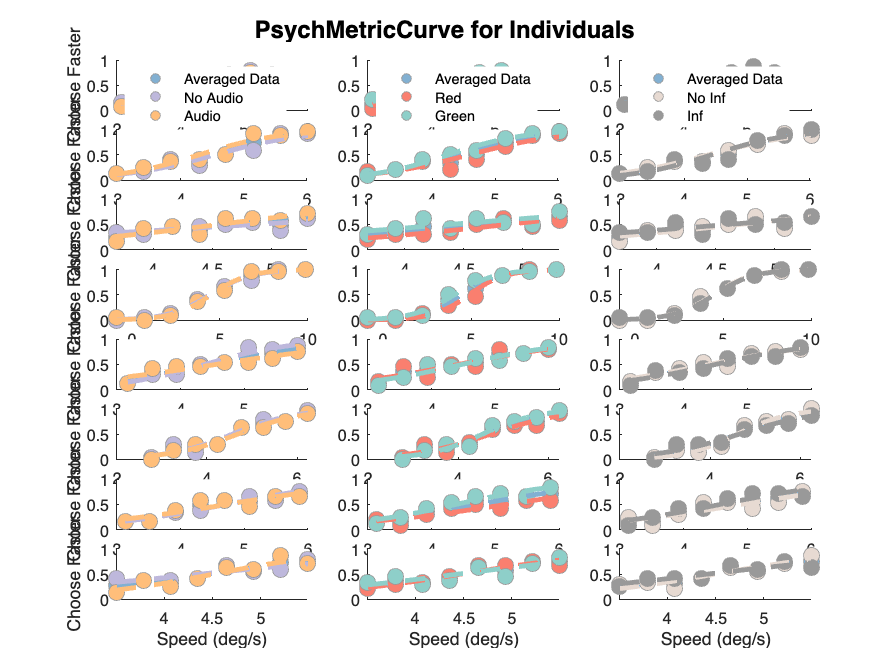


sgtitle('PsychMetricCurve for Individuals ','FontWeight','bold')

f1 = gcf;

PSEs

PSEs =     5.0581    5.4393    4.7304    5.4860    4.6229    5.6939    4.5730
    4.4147    4.5437    4.2923    4.5893    4.2560    4.3894    4.4381
    4.6632    4.8683    4.5577    4.8749    4.3856    4.7012    4.6146
    4.4679    4.4357    4.5000    4.8840    4.0495    4.4358    4.5000
    4.4531    4.3818    4.5598    4.4265    4.4775    4.4025    4.5000
    4.6296    4.5700    4.6903    4.7252    4.5449    4.6108    4.6538
    4.7259    4.7235    4.7293    5.1779    4.3841    4.9026    4.5741
    4.4680    4.3851    4.5172    4.4804    4.4531    4.5000    4.4239


JNDs

JNDs =     1.7785    1.9729    1.5915    1.7303    1.7679    2.1406    1.4591
    0.7622    0.8061    0.7095    0.8470    0.6655    0.8291    0.6995
    1.2552    1.8906    0.9248    1.0739    1.4489    1.0996    1.4520
    1.2375    1.2927    1.1807    1.1222    1.2941    1.2290    1.2457
    1.0244    0.7607    1.4207    1.0920    0.9621    1.0824    0.9696
    0.7973    0.7762    0.8167    0.9236    0.6800    0.6415    0.9754
    1.2018    1.0913    1.3294    1.4328    0.9847    1.3280    1.0864
    0.9983    1.4248    0.7443    0.8939    1.1236    0.8262    1.2355


d_primes

d_primes =     1.1051    0.9960    1.2261    1.1103    1.1287    1.0181    1.2212
    1.3519    1.2848    1.4357    1.2868    1.4450    1.3207    1.3837
    0.5439    0.3174    0.7770    0.6838    0.4215    0.5596    0.5291
    2.2266    2.1556    2.3007    2.2256    2.2854    2.1556    2.3007
    0.9195    1.2261    0.6375    0.8910    0.9483    0.8058    1.0368
    1.5781    1.6636    1.4974    1.3976    1.7756    1.9036    1.2901
    0.8535    1.0162    0.6968    0.7267    1.0099    0.7058    1.0081
    0.8473    0.6382    1.0669    0.9483    0.7485    0.9776    0.7209


criterions

criterions =     0.2063    0.3142    0.0946    0.3714    0.0459    0.3781    0.0315
   -0.0656    0.0321   -0.1693    0.0643   -0.2041   -0.0812   -0.0498
    0.0882    0.1326    0.0422    0.2372   -0.0534    0.1225    0.0541
   -0.0121   -0.0233         0    0.1454   -0.1753   -0.0233         0
   -0.0290   -0.0946    0.0275   -0.0433   -0.0146   -0.0567         0
    0.0981    0.0554    0.1384    0.1503    0.0387    0.1027    0.0965
    0.1218    0.1340    0.1112    0.3111   -0.0742    0.1956    0.0445
   -0.0214   -0.0550    0.0151   -0.0146   -0.0280         0   -0.0418


% vars = {'PSE','JND','d_prime','criterion'};
% cons = {'NoAud', 'Aud'};
% bootnum = 50;
% for v = [1:length(vars)]
%     for c = [1:length(cons)]
%         eval(sprintf('%s_%s=%ss(:,%d);',vars{v},cons{c},vars{v},c+1));
%     end
%     temp_red = eval(sprintf('%s_red;',vars{v}));
%     temp_green = eval(sprintf('%s_green;',vars{v}));
%     [h,p,ci,stats] = ttest(temp_red,temp_green,'Alpha',0.05);
%     eval(sprintf('%s_Stats = [mean(%s_red);mean(%s_green);stats.tstat;p];',vars{v},vars{v},vars{v}));
%
%     % after bootstrapping
%     [bootstats,bootsam] = bootstrp(500,@mean,[temp_red,temp_green]);
%     [h,p,ci,stats] = ttest(bootstats(:,1),bootstats(:,2),"Alpha",0.05);
%     temp_cm = sprintf('%s_Bootstats = [mean(bootstats(:,1));mean(bootstats(:,2));stats.tstat;p];',vars{v});
%     eval(temp_cm)
% end

Error using eval
Unrecognized function or variable 'PSE_red'.

%
% compare_table = table(PSE_Stats,PSE_Bootstats,JND_Stats,JND_Bootstats,...
%     d_prime_Stats,d_prime_Bootstats,criterion_Stats,criterion_Bootstats,...
%     'RowNames',{'M(red)';'M(green)';'t-value';'p'})

## BarPlot

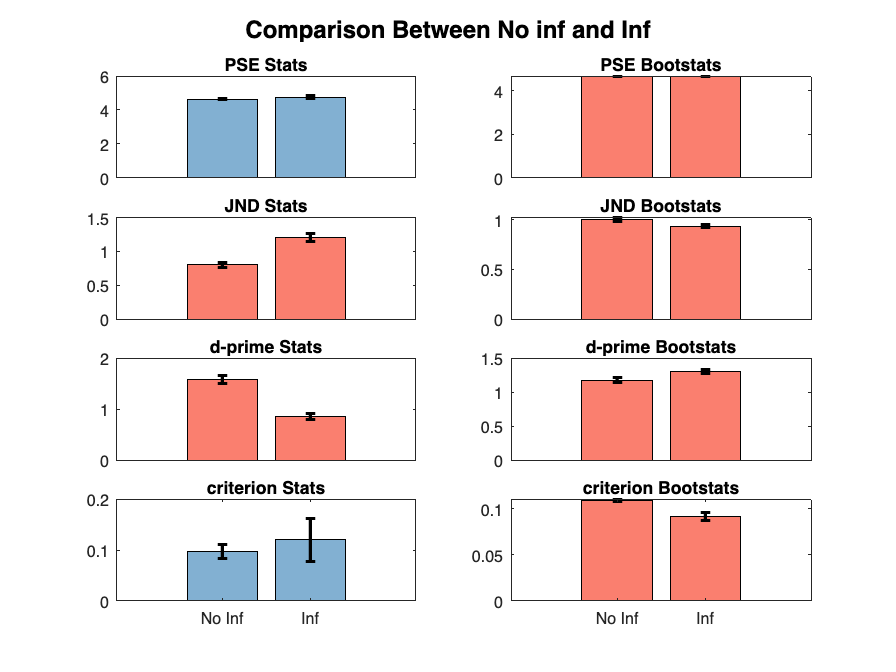

vars = {'PSEs','JNDs','d_primes','criterions'};
vars_rn = {'PSE','JND','d-prime','criterion'};
statis = {'Stats','Bootstats'};

figure;
pi = 1;
for vi = 1:length(vars)
    temp_dt = eval(sprintf('%s(6:7,:);',vars{vi}));
    temp_con1 = temp_dt(1,:); temp_con2 = temp_dt(2,:);
    [h,p,ci,stats] = ttest(temp_con1,temp_con2,'Alpha',0.05);
    eval(sprintf('%s_Stats = [mean(temp_con1);mean(temp_con2);stats.tstat;p];',vars{vi}));
    % after bootstrapping
    [bootstats,bootsam] = bootstrp(50,@mean,[temp_con1;temp_con2]);
    [bh,bp,bci,bstats] = ttest(bootstats(:,1),bootstats(:,2),"Alpha",0.05);
    temp_cm = sprintf('%s_Bootstats = [mean(bootstats(:,1));mean(bootstats(:,2));bstats.tstat;bp];',vars{vi});
    eval(temp_cm)
    for si = 1:length(statis)
        subplot(4,2,pi); pi = pi +1;
        current_dt = eval(sprintf('%s_%s',vars{vi},statis{si}));
        if current_dt(4) < 0.05
            draw_color = "#FA7F6F";
        elseif (current_dt(4) >= 0.05) && (current_dt(4) < 0.1)
            draw_color = "#8ECFC9";
        else
            draw_color = "#82B0D2";
        end
        bar(current_dt(1:2),'FaceColor',draw_color)
        title(sprintf('%s %s',vars_rn{vi},statis{si}))
        if vi == length(vars)
            set(gca,'XTickLabel',{'No Inf','Inf'});
        else
            xticks('')
        end
        hold on
        if si ==1
            se = [std(temp_con1)/sqrt(length(subids)),std(temp_con2)/sqrt(length(subids))];
            errorbar(mean([temp_con1',temp_con2'])',se,'LineWidth',2,'Color','black','LineStyle','none');
        else
            se = [std(bootstats(:,1))/sqrt(50);std(bootstats(:,2))/sqrt(50)];
            errorbar(current_dt(1:2),se,'LineWidth',2,'Color','black','LineStyle','none');
        end
    end
end

sgtitle('Comparison Between No inf and Inf','FontWeight','bold');

f2 = gcf;

## Comparisons

ids = [1:8];

anova_PSEs = zeros(length(ids),4); % audio / color / interference
anova_JNDs = zeros(length(ids),4);
anova_d_primes = zeros(length(ids),4);
anova_criterions = zeros(length(ids),4);
targets = [0.25, 0.5, 0.75]; % 25%, 50% and 75% performance
weights = ones(1,length(all_exp_levels)); % No weighting
for id = ids
    load(['Results_',num2str(id),'.mat']);

    col_con = all_conds(:,3);
    inf_con = all_conds(:,4);
    aud_con = all_conds(:,5);
    V_exp = round(V_exp / (mean(V_con)/ 4.5),2);
    Summary_table = table(V_exp,aud_con,col_con,inf_con,res,correct_ans,yesno,RTs);
    Summary_table = renamevars(Summary_table,["res","correct_ans","yesno","RTs"],...
        ["res","exphigher","accuracy","RT"])
    %     % Clean data; rid of extreme RTs
    %     idx  = find(abs(Summary_table.RTs - mean(Summary_table.RTs))...
    %         < 3*std(Summary_table.RTs));
    %     Summary_table = Summary_table(idx,:);
    fillin = 1;
    for xi = 1:2
        for zi = 1:2
            mean_acc = groupsummary(Summary_table,"V_exp",'mean').mean_accuracy;
            all_exp_levels = groupsummary(Summary_table,"V_exp").V_exp;
            Summary_con1 = Summary_table(...
                (Summary_table.aud_con == xi) & (Summary_table.inf_con == zi),:);
            acc = groupsummary(Summary_con1,"V_exp",'mean').mean_accuracy;
            choose_exp = zeros(length(all_exp_levels),1);
            choose_exp([1:4],:) = 1 - acc([1:4],:);
            choose_exp(5:end,:) = acc(5:end);
            % Calculate the dprime and criterion
            [dprime_temp,c_temp] = dprime(mean(choose_exp([5:8],1)),mean(choose_exp([1:4],1)));
            anova_d_primes(id,fillin) = dprime_temp;
            anova_criterions(id,fillin) = c_temp;
            % PSE
            [coeffs_all, stats_all, curve_all, threshold_all] = ...
                FitPsychCurveLogit(all_exp_levels, choose_exp(:,1), weights, targets);
            anova_PSEs(id,fillin) = [threshold_all(2)]; % audio / color / interference
            anova_JNDs(id,fillin) = [(threshold_all(3) - threshold_all(1))/2];
            fillin = fillin + 1;
        end
    end
end

Summary_table = 384×8 table
    V_exp    aud_con    col_con    inf_con    res    exphigher    accuracy      RT   
    _____    _______    _______    _______    ___    _________    ________    _______

    4.16        2          1          2        2       false       true        1.9055
    6.19        2          2          1        2       true        true        1.1025
    6.19        2          1          1        1       true        true       0.81725
    6.19        1          2          2        0       true        false           -1
    3.49        1          2          2        1       false       true        1.0811
    4.84        2          2          2        2       true        true       0.54327
    5.51   

Summary_table = 384×8 table
    V_exp    aud_con    col_con    inf_con    res    exphigher    accuracy      RT   
    _____    _______    _______    _______    ___    _________    ________    _______

    5.59        2          2          1        1       true        false       0.6579
    5.59        1          1          1        1       true        true        1.1233
    2.98        1          2          2        1       false       true       0.29848
    4.71        2          2          2        2       true        true       0.42969
    3.84        1          2          1        1       false       true       0.41907
    3.41        1          1          1        2       false       true       0.62308
    5.59   

Summary_table = 384×8 table
    V_exp    aud_con    col_con    inf_con    res    exphigher    accuracy      RT   
    _____    _______    _______    _______    ___    _________    ________    _______

    4.61        1          1          1        2       true        false      0.33646
    4.61        2          2          1        2       true        true       0.30894
    5.08        1          2          1        2       true        true       0.28419
    4.39        2          1          1        2       false       true       0.32523
    5.31        2          2          2        2       true        true       0.76601
    4.39        2          2          1        2       false       false      0.33992
    3.69   

Summary_table = 384×8 table
    V_exp    aud_con    col_con    inf_con    res    exphigher    accuracy       RT   
    _____    _______    _______    _______    ___    _________    ________    ________

     5.27       2          1          1        2       true        false       0.82269
    -0.86       2          2          2        2       false       false       0.57755
     5.27       2          2          1        1       true        false       0.25927
     0.69       1          2          2        1       false       true       0.013475
     3.73       2          2          1        2       false       false       0.20986
     8.31       1          1          2        1       true        true         1.5735
   

Summary_table = 384×8 table
    V_exp    aud_con    col_con    inf_con    res    exphigher    accuracy      RT   
    _____    _______    _______    _______    ___    _________    ________    _______

    3.94        2          2          2        1       false       true       0.72145
    3.17        2          1          1        1       false       false       1.8138
    3.56        2          2          1        1       false       true       0.63349
    4.31        2          2          2        1       false       true        1.0767
    3.94        1          2          2        1       false       true       0.99075
    4.31        2          1          2        2       false       true       0.97666
    5.44   

Summary_table = 384×8 table
    V_exp    aud_con    col_con    inf_con    res    exphigher    accuracy      RT   
    _____    _______    _______    _______    ___    _________    ________    _______

    6.24        2          1          2        1       true        true        0.5865
    2.76        2          2          2        1       false       true       0.77076
    6.24        2          2          2        1       true        false       1.6011
    5.74        2          1          2        1       true        true       0.69144
    4.76        1          1          1        2       true        false       2.3619
    3.75        2          1          1        0       false       true            -1
    2.76   

Summary_table = 384×8 table
    V_exp    aud_con    col_con    inf_con    res    exphigher    accuracy       RT    
    _____    _______    _______    _______    ___    _________    ________    _________

    3.92        2          2          2        2       false       false        0.36029
    5.49        2          2          1        2       true        true         0.28396
    4.31        1          1          1        1       false       false        0.32201
    3.51        1          2          1        1       false       true         0.27363
    5.49        1          1          2        2       true        false         0.2871
    3.51        1          2          1        1       false       true         0.2

Summary_table = 384×8 table
    V_exp    aud_con    col_con    inf_con    res    exphigher    accuracy      RT   
    _____    _______    _______    _______    ___    _________    ________    _______

    5.49        2          2          1        2       true        true        1.2183
    3.51        2          1          2        2       false       true        1.0868
    3.79        1          1          2        2       false       true        0.9922
    4.07        2          2          2        1       false       true       0.69154
    3.79        2          1          2        2       false       true        1.5726
    3.51        2          2          2        2       false       false       1.2168
    5.49   



anova_PSEs

anova_PSEs =     6.0443    4.9770    5.3920    4.2306
    4.4525    4.6222    4.3335    4.2514
    4.7457    5.0538    4.6774    4.4164
    4.2418    4.6283    4.6279    4.3714
    4.2570    4.5000    4.6248    4.5000
    4.6766    4.4499    4.5444    4.8646
    4.7035    4.7427    5.1657    4.4000
    4.0500    4.5428    4.6293    4.2487


anova_PSEs = anova_PSEs(:)

anova_PSEs =     6.0443
    4.4525
    4.7457
    4.2418
    4.2570
    4.6766
    4.7035
    4.0500
    4.9770
    4.6222


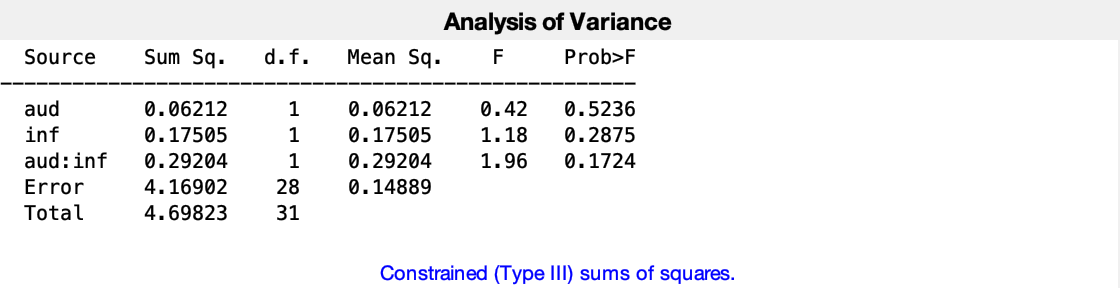

p =     0.5236
    0.2875
    0.1724


table = 6×7 cell array
    {'Source' }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'  }
    {'aud'    }    {[ 0.0621]}    {[   1]}    {[        0]}    {[  0.0621]}    {[  0.4172]}    {[  0.5236]}
    {'inf'    }    {[ 0.1750]}    {[   1]}    {[        0]}    {[  0.1750]}    {[  1.1757]}    {[  0.2875]}
    {'aud:inf'}    {[ 0.2920]}    {[   1]}    {[        0]}    {[  0.2920]}    {[  1.9614]}    {[  0.1724]}
    {'Error'  }    {[ 4.1690]}    {[  28]}    {[        0]}    {[  0.1489]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[ 4.6982]}    {[  31]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
         source: 'anovan'
          resid: [32×1 double]
         coeffs: [9×1 double]
            Rtr: [4×4 double]
       rowbasis: [4×9 double]
            dfe: 28
            mse: 0.1489
    nullproject: [9×4 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {9×1 cell}
           vars: [9×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: [4×4 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


term =      1     0
     0     1
     1     1



aud = strcat({'Aud'},num2str([ones(16,1);2*ones(16,1)]));
inf = strcat({'Inf'},num2str([ones(8,1);2*ones(8,1)]));
inf =[inf;inf];


varnames={'aud','inf'};

[p,table,stats,term]=anovan(anova_PSEs,...
    {aud,inf},'model','full','varnames',varnames)

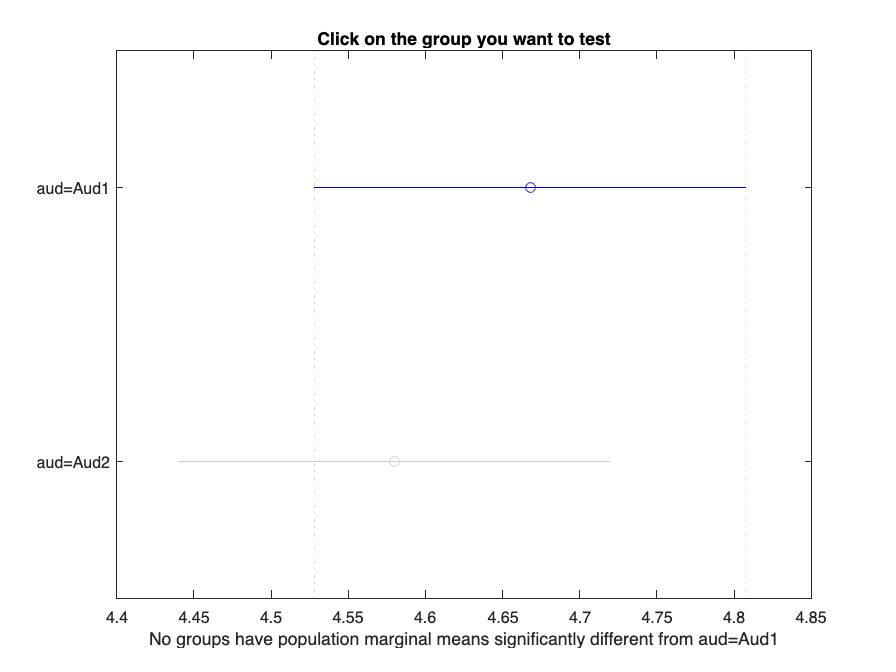

c =     1.0000    2.0000   -0.1913    0.0881    0.3676    0.5236


m =     4.6680    0.0965
    4.5799    0.0965


h =   Figure (4: Multiple comparison of population marginal means) with properties:

      Number: 4
        Name: 'Multiple comparison of population marginal means'
       Color: [1 1 1]
    Position: [616 598 560 420]
       Units: 'pixels'

  Show all properties


gnames = 2×1 cell array
    {'aud=Aud1'}
    {'aud=Aud2'}


[c,m,h,gnames]=multcompare(stats)